# Example: Free flight

This example will allow you to have the AR Drone 2.0 hover in free flight. Note that this example does not use the bottom camera to determine the drift like the default AR Drone 2.0 program. The Drone will drift using this model, make sure you try this model in a safe environment.

## Achieving free flight:

To have your AR Drone 2.0 freely fly, follow the steps below.

    1.    Make sure the AR Drone 2.0 sensors are calibrated. To do so please follow the **Calibrating the sensors **example in this documentation.

    2.    Open the free flight model by evaluating:

Free_Flight

This wil open the following model:

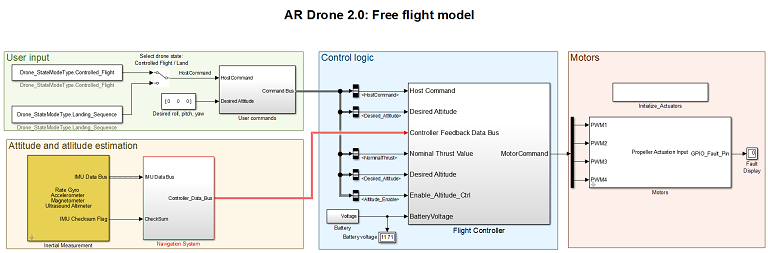

    3.    Set the drone state to **Landing_sequence.** To do this make sure the selector switch in the **User input **area in the Simulink model is set to the **Landing_sequence** input as shown below. Also keep the roll, pitch and yaw angles at 0 if you want the drone to hover.

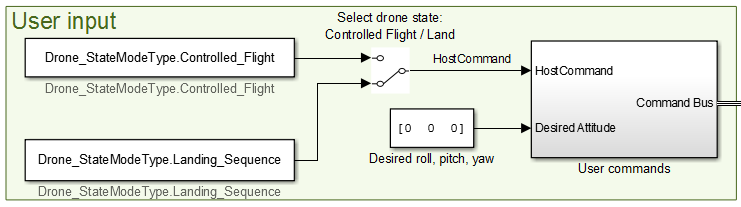

    4.    **Build** the model. Either click the **Build** button   or press **control** + **B**.

    5.    **Connect** the Simulink model to the AR Drone. Click the **Connect** **to target **button  

    6.    **Run** the Simulink model. Click the **Run** button  

    7.    With the AR Drone 2.0 in a safe position, switch the **User input drone state selector** to **Controlled_Flight**. This will cause the AR Drone 2.0 to take off and hover.

    8.    When you want to stop hovering, switch the **User input drone state selector** to **Landing_Sequence**. This will cause the AR Drone 2.0 to land.

**Note:** If the battery voltage drops below 10.1V or if the drone determines the pitch or roll angle unsafe, the drone wil land automically.

    9.    Either make the drone hover again by following step 7, or stop the model by clicking the **stop **  button.

# Model background

## User input 

The **User** **input** area allows you to apply some high level control to the AR Drone 2.0. It is shown in the image below.;

In this section you can:

    1.    Change the **drone** **state** between flight and landing

    2.    Set the **desired** **roll** and **pitch** **angles** and the **yaw** **rate**.

By opening the User commands block you gain access to:

    1.    **Nominal** **thrust** **value**. This PWM value [0% - 100%] is used as the initial thrust for take-off.

    2.    High and low **hovering** **height** and **mode**. You can select two hovering heights in cm, and toggle between the two.

    3.    Enable or disable **height** **control**. With height control disabled the AR Drone 2.0 will hover at the height it achieves with the set nominal thrust value.

## Attitude and altitude estimation

The **Attitude and altitude estimation **area contains.

    1.    The **Inertial Measurement** Simulink block for reading the AR Drone 2.0 sensor data

    2.    The **Navigation System** block for computing the attitude and altitude from the sensor data

This area is shown below.

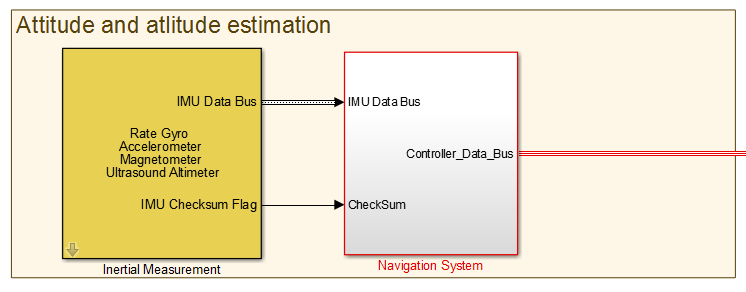

The **Inertial Measurement** block retrieves the AR Drone 2.0 sensor data. To learn more about how it works please see the **Sensor drivers **section under **Integrating drivers **in the **Concepts **are of the documentation. While the IMU refreshes at 200Hz on the drone, the sample rate is set to 400Hz for this example because that is what the flight controller is tuned for.

The **Navigation System **block processes the raw IMU data to retrieve the euler angles, body rates and ultrasound data from the drone. It has the following sub blocks:

    1.    **Verify IMU Data** This MATLAB function block ensures that no corrupt IMU data is used for computation.

    2.    **Create measurement bus: **Not all data coming from the IMU is interesting. The relevant data is selected and formatted into a data bus object.

    3.    **Measument calibration correction: **The raw IMU data is scaled and offset using calibrated parameters. These parameters are stored in the ArDroneDataDictionary. To learn more about this read the **Data dictionaries **section in the **Concepts **section of this documentation.

    4.    **Kalman filter: **A set of kalman filters are used with sensor fusion between the accelerometer and gyroscope to determine the euler angles of the AR Drone 2.0.

## Control logic

The **Control logic **area contains the **Flight controller** and **Battery **blocks. These are used for:

    1.    High level control strategies such as land or fly. 

    2.    Low level control, meaning computing the signals that are send to the motors.

This area is shown below.

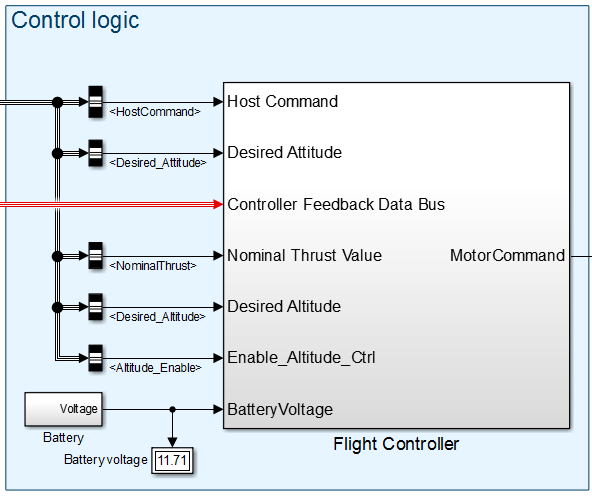

# TODO EXPLAIN FLIGHT CONTROLLER

## Motors

The **Motors **area contains the **Motors **and **Initialize Actuators **blocks. These blocks interface the computed motor commands with the AR Drone 2.0 motors.

This area is shown below.

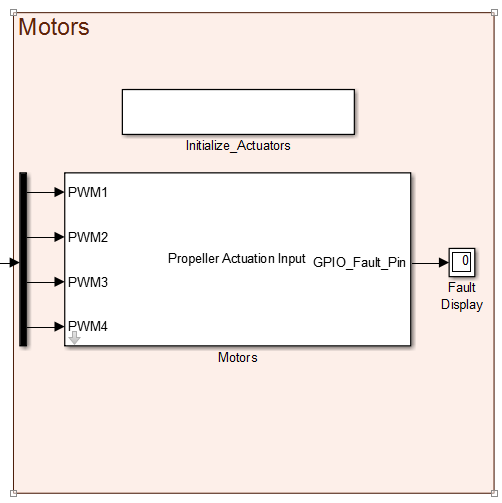

The **Initialize_actuators **block initializes both the motors on the AR Drone 2.0 as well as the LEDs. This block is required in any model which uses the LEDs or motors.

The **Motors **block takes PWM signals (0% - 100%) to control each individual motor. To lean more about how this block interfaces with the AR Drone 2.0 motors please read the **Actuator drivers **section under **Integrating drivers **in the **Concepts **are of the documentation.

If a propeller hits anything the AR Drone 2.0 motor boards will turn off. This is visible in the Simulink model by the Fault Display changing from 0 to 1. You will need to rebuild the model if this happens.